Task 1

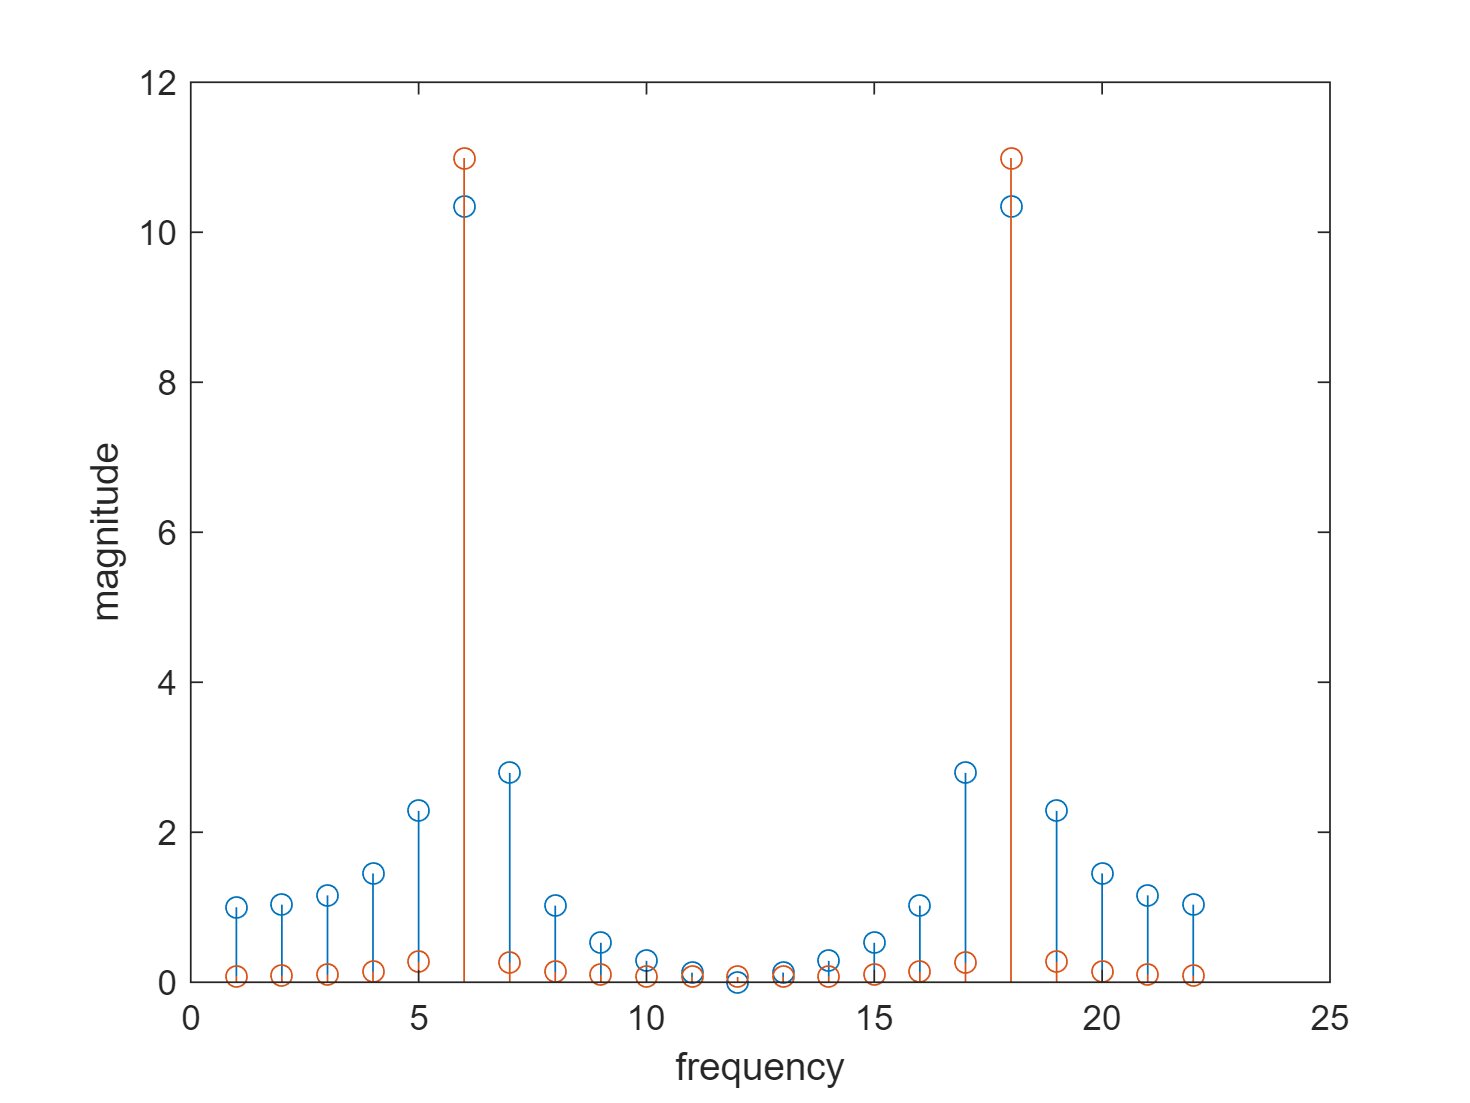

clear
n=0:21;
w1=(10*pi)/21;
w2=(9.5*pi)/21;
x1=cos(w1*n);
x2=cos(w2*n);
X1=fft(x1);
X2=fft(x2);
m1=abs(X1);
m2=abs(X2);
stem(m1);hold on;
stem(m2);
hold off;
xlabel('frequency');
ylabel('magnitude');

Task 2

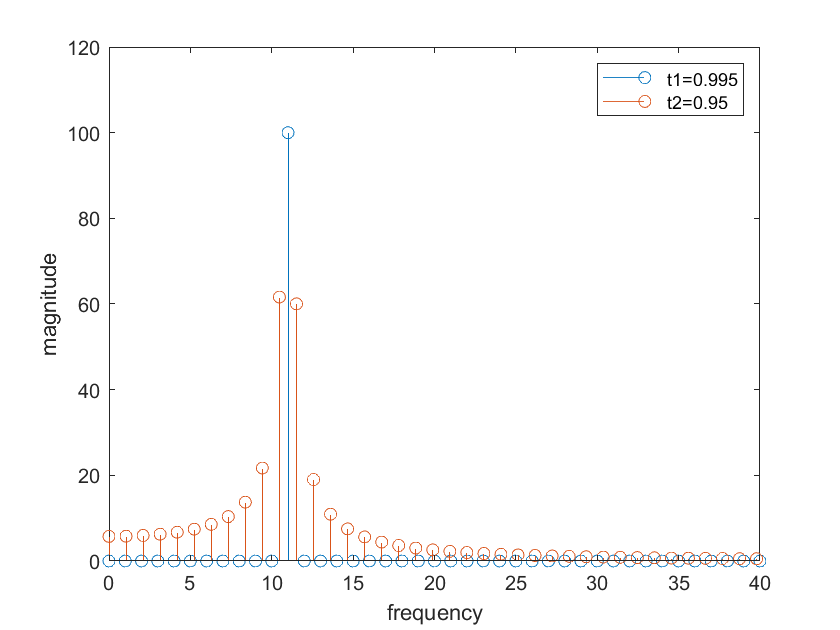

clear;
fs=200;
T=1/fs;
freq=11;
t1=0:T:0.995;
n1=length(t1);
df1=fs/n1;
t2=0:T:0.95;
n2=length(t2);
df2=fs/n2;
x1=sin(2*pi*freq*t1);
x2=sin(2*pi*freq*t2);
X1=fft(x1);
X2=fft(x2);
m1=abs(X1);
m2=abs(X2);
f1=df1*(0:n1-1);
stem(f1,m1);
hold on
f2=df2*(0:n2-1);
stem(f2,m2);
xlim([0 40]);
xlabel('frequency');
ylabel('magnitude');
legend('t1=0.995','t2=0.95');
hold off;

Task 3

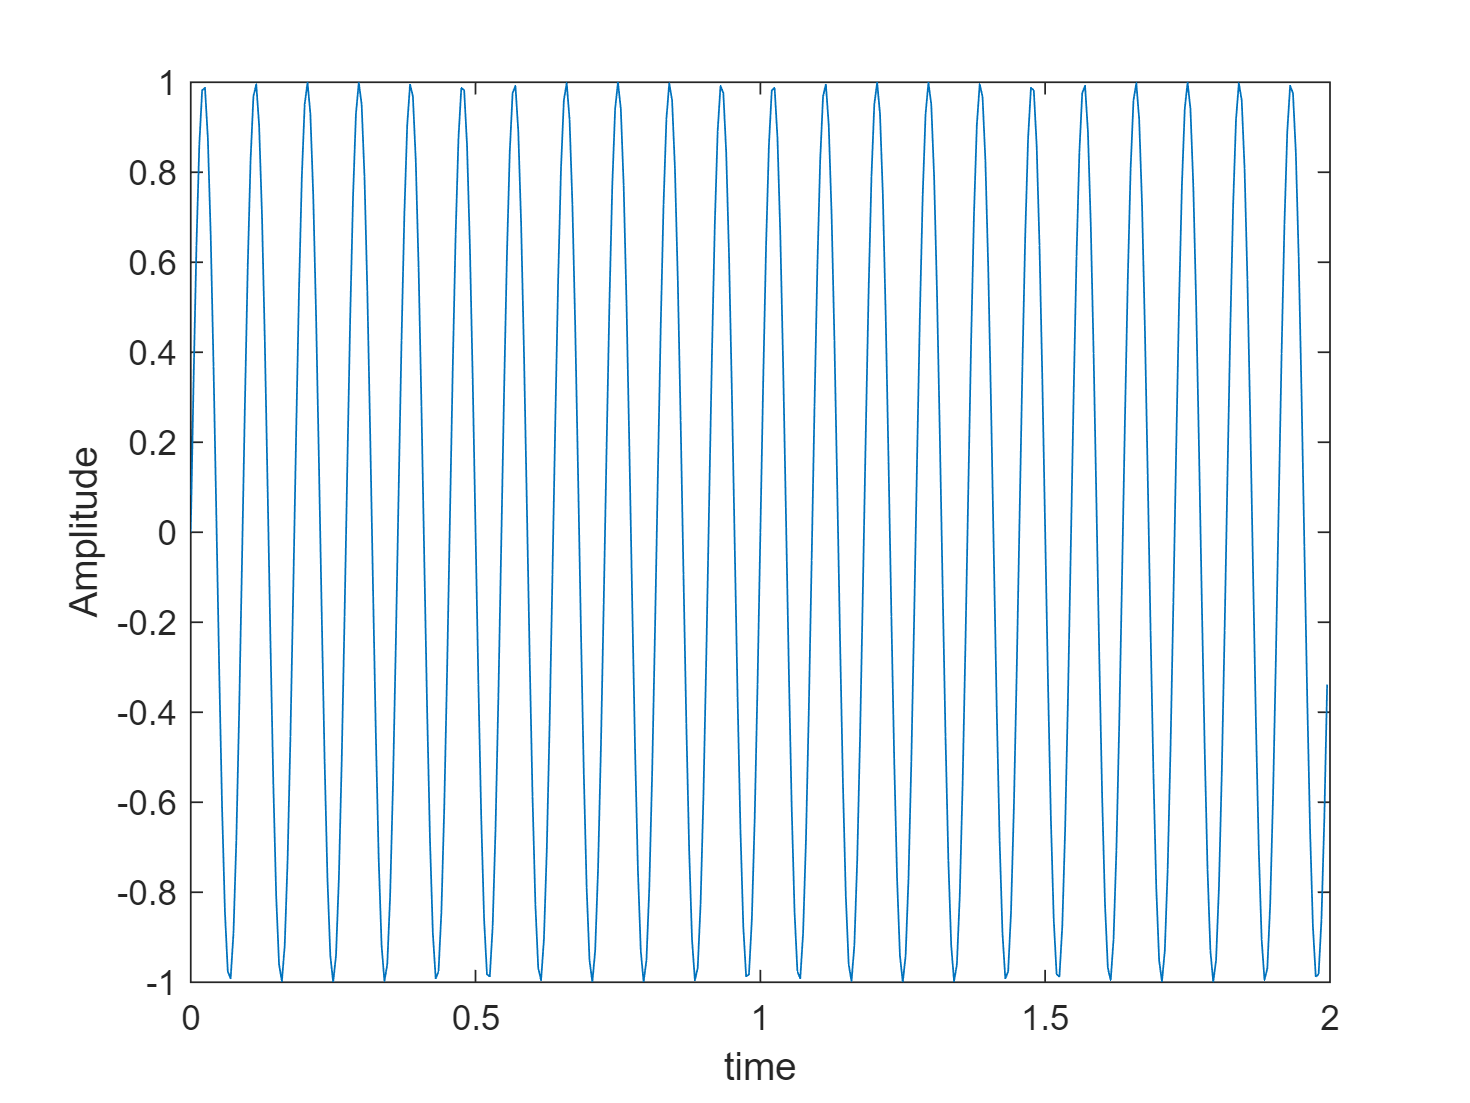

t3=0:T:0.995*2+T;
x=[x1,x1];
plot(t3,x);
xlabel('time');
ylabel('Amplitude');

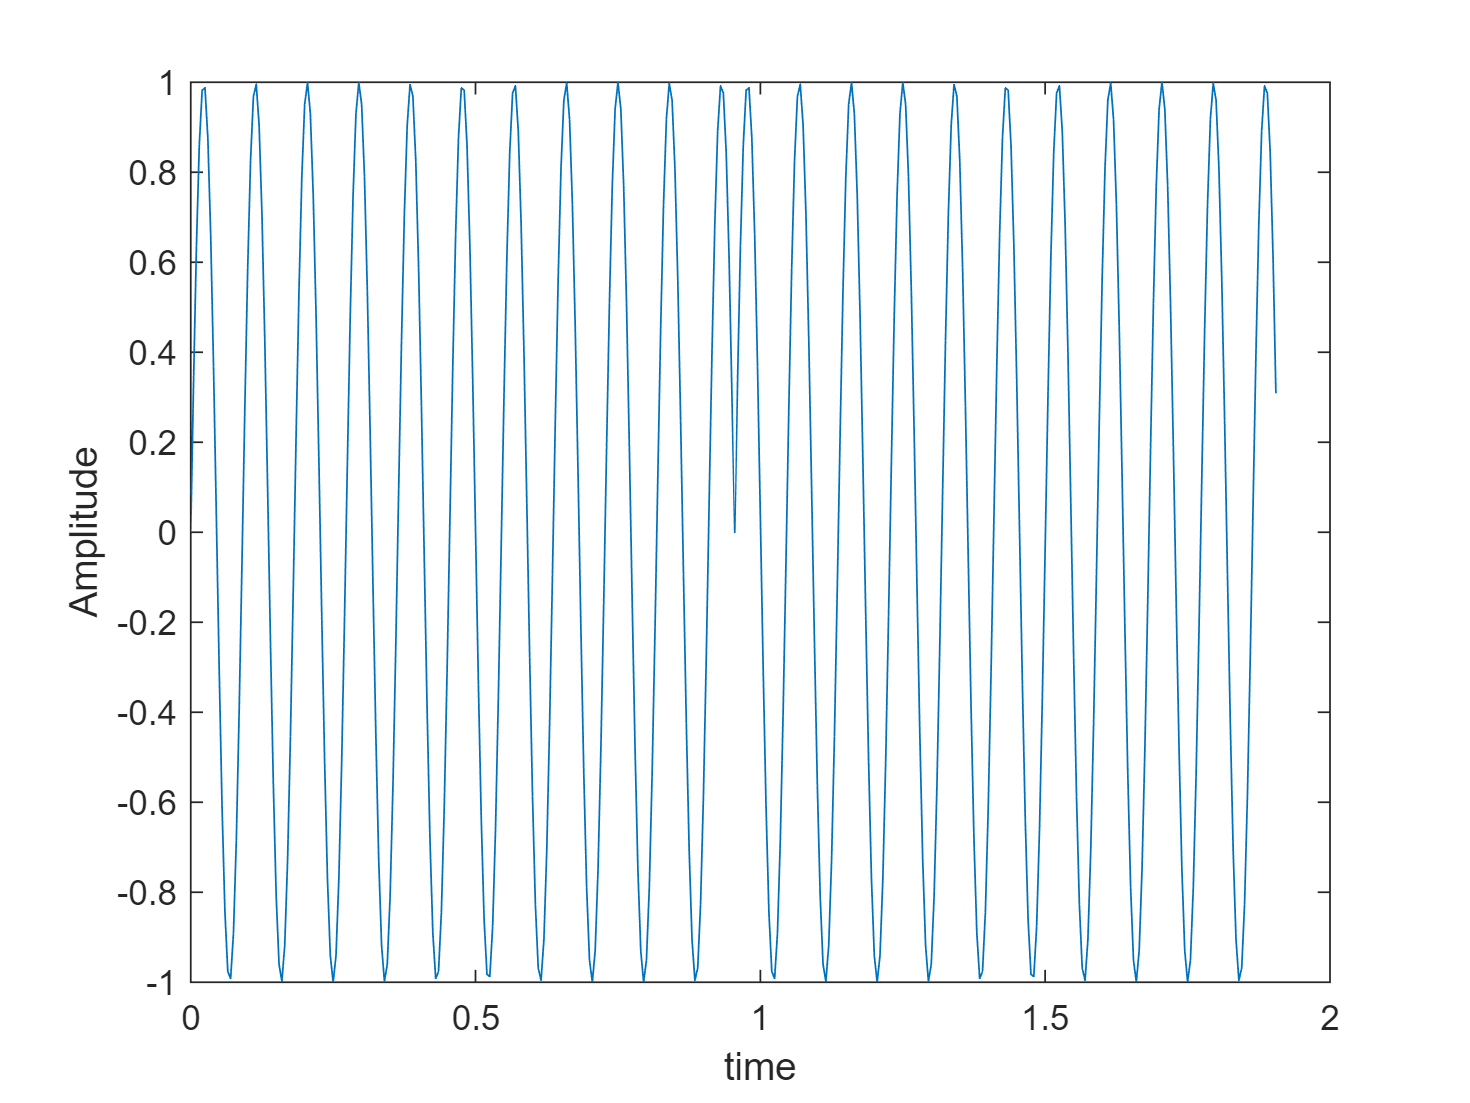

t4=0:T:0.95*2+T;
x3=[x2,x2];
plot(t4,x3);
xlabel('time');
ylabel('Amplitude');

Task 4

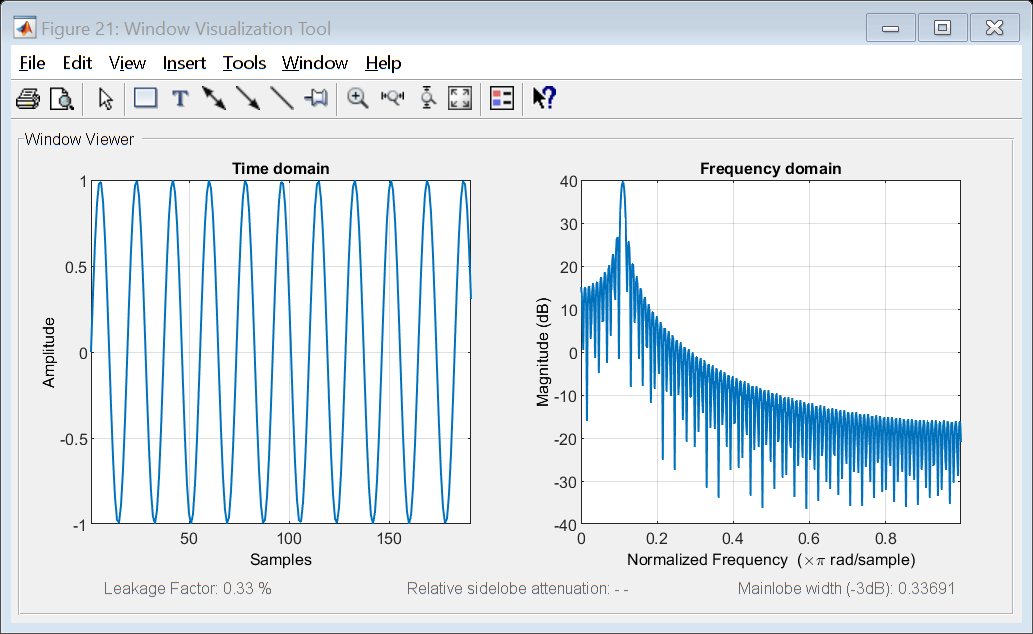

clear;
fs=200;
T=1/fs;
freq=11;
t=0:T:0.95;
n=length(t);
df=fs/n;
x=sin(2*pi*freq*t);
w=rectwin(191);
wx=x.*w';
wvtool(x)

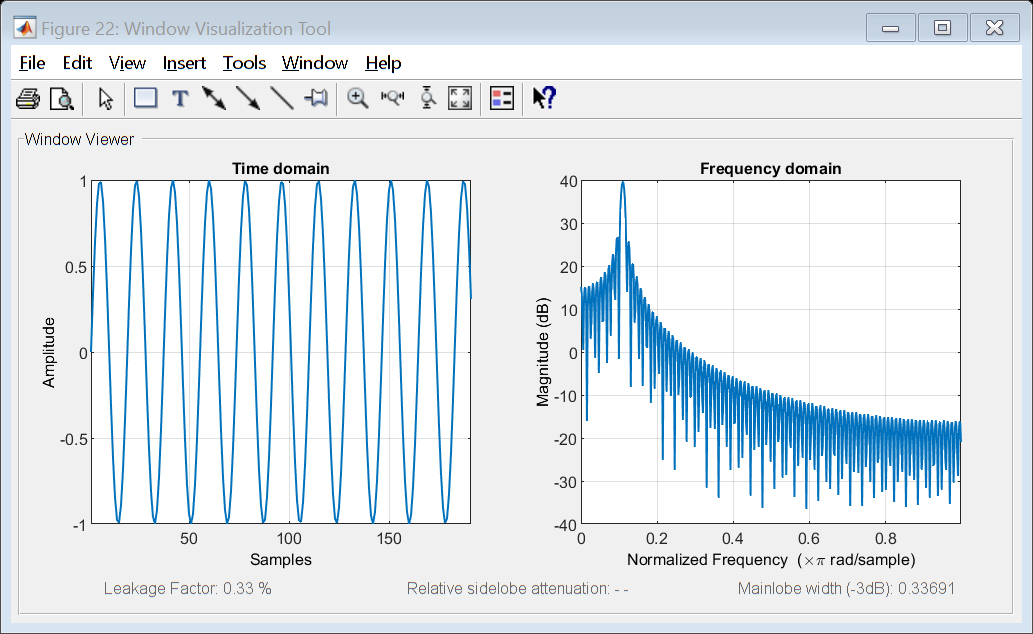

wvtool(wx)

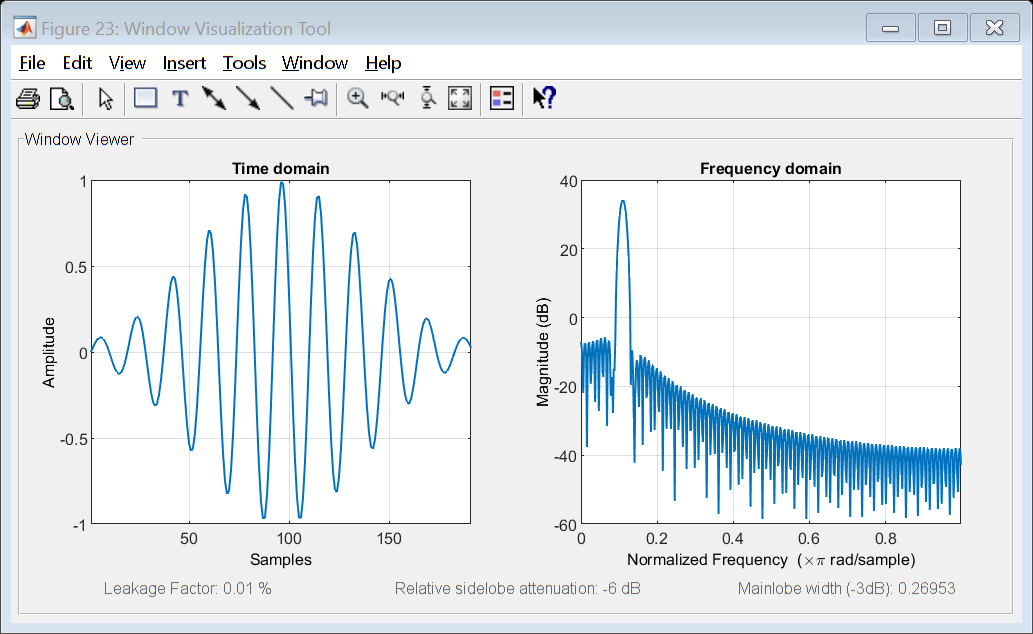

w2=hamming(191);
wx2=x.*w2';
wvtool(wx2)

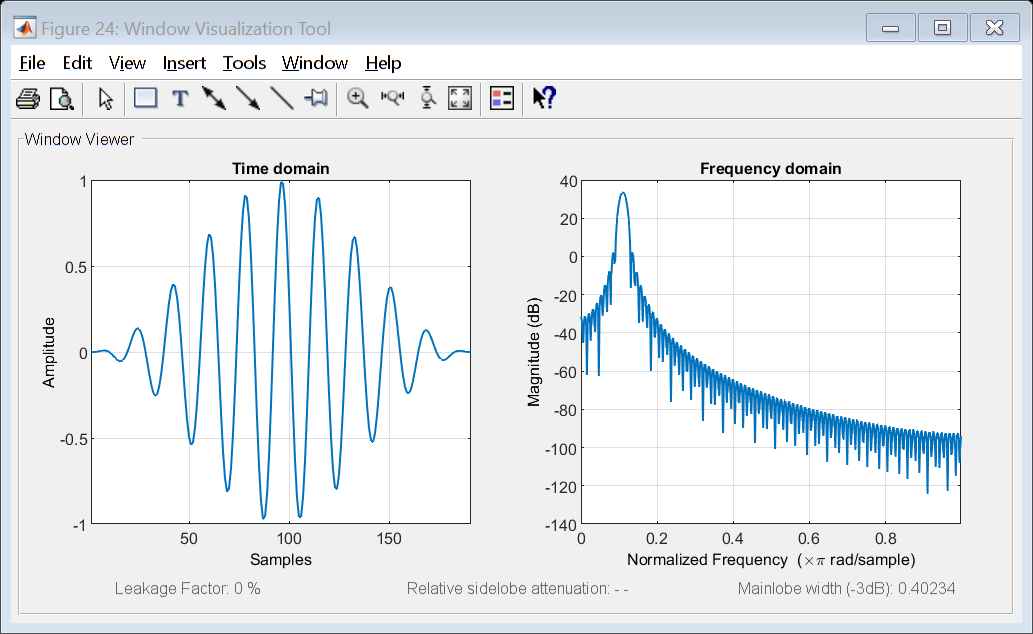

w3=hann(191);
wx3=x.*w3';
wvtool(wx3);

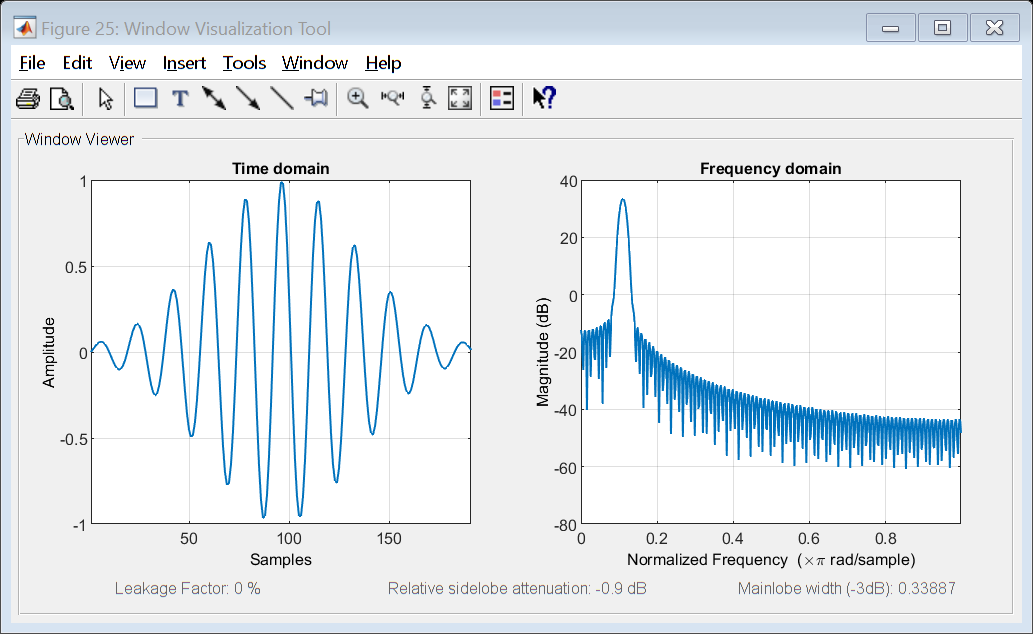

wx4=x.*gausswin(191)';
wvtool(wx4)

Task 5

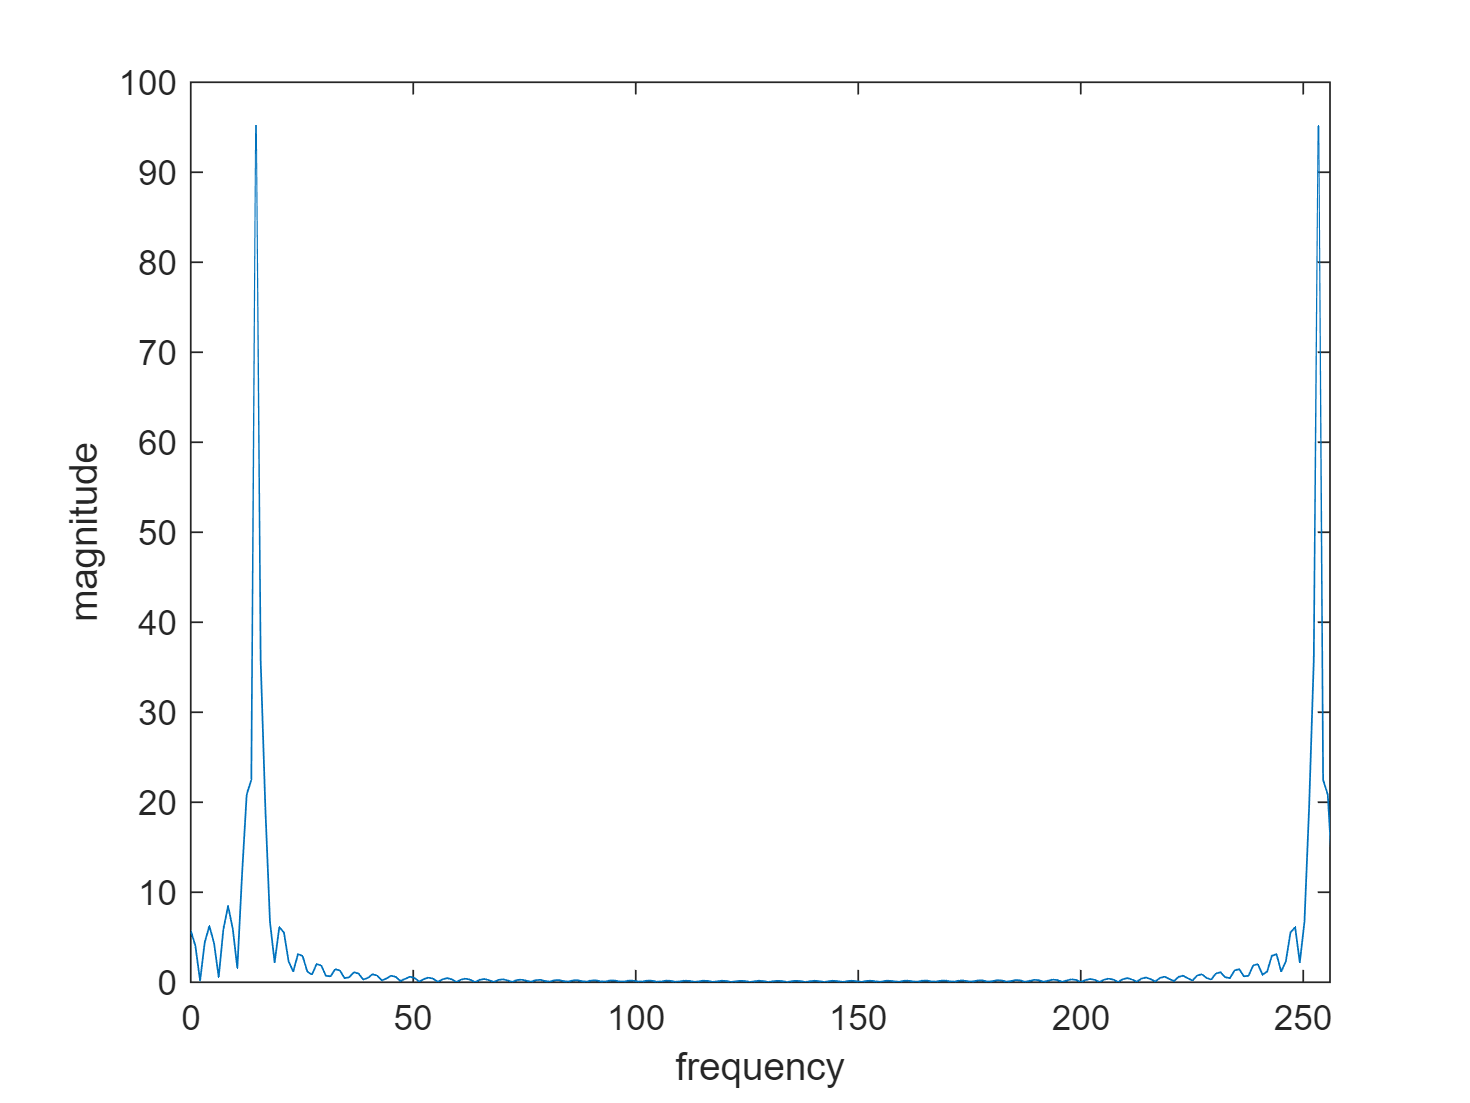

X0=fft(x,256);
X=fft(wx,256);
X2=fft(wx2,256);
X3=fft(wx3,256);
X4=fft(wx4,256);
f=df*(0:256-1);
plot(f,abs(X0))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

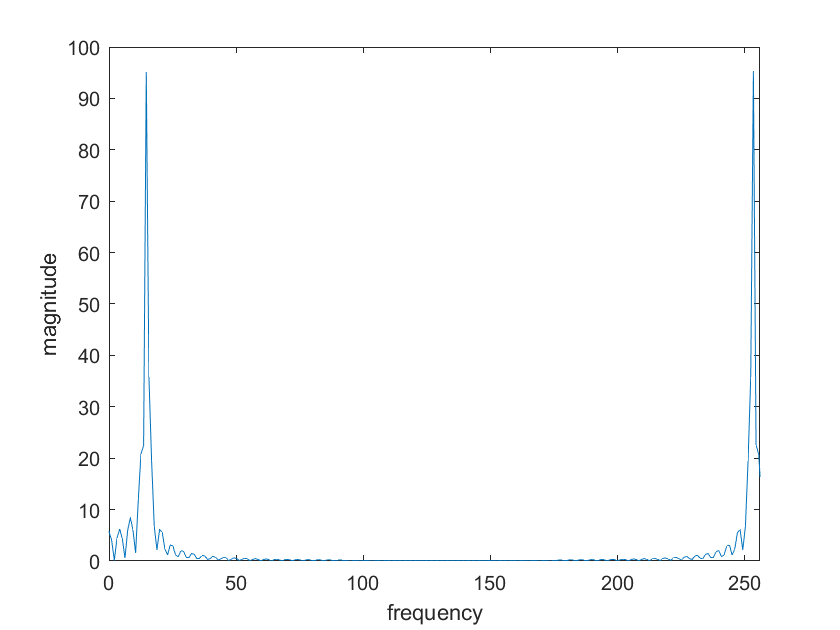

plot(f,abs(X))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

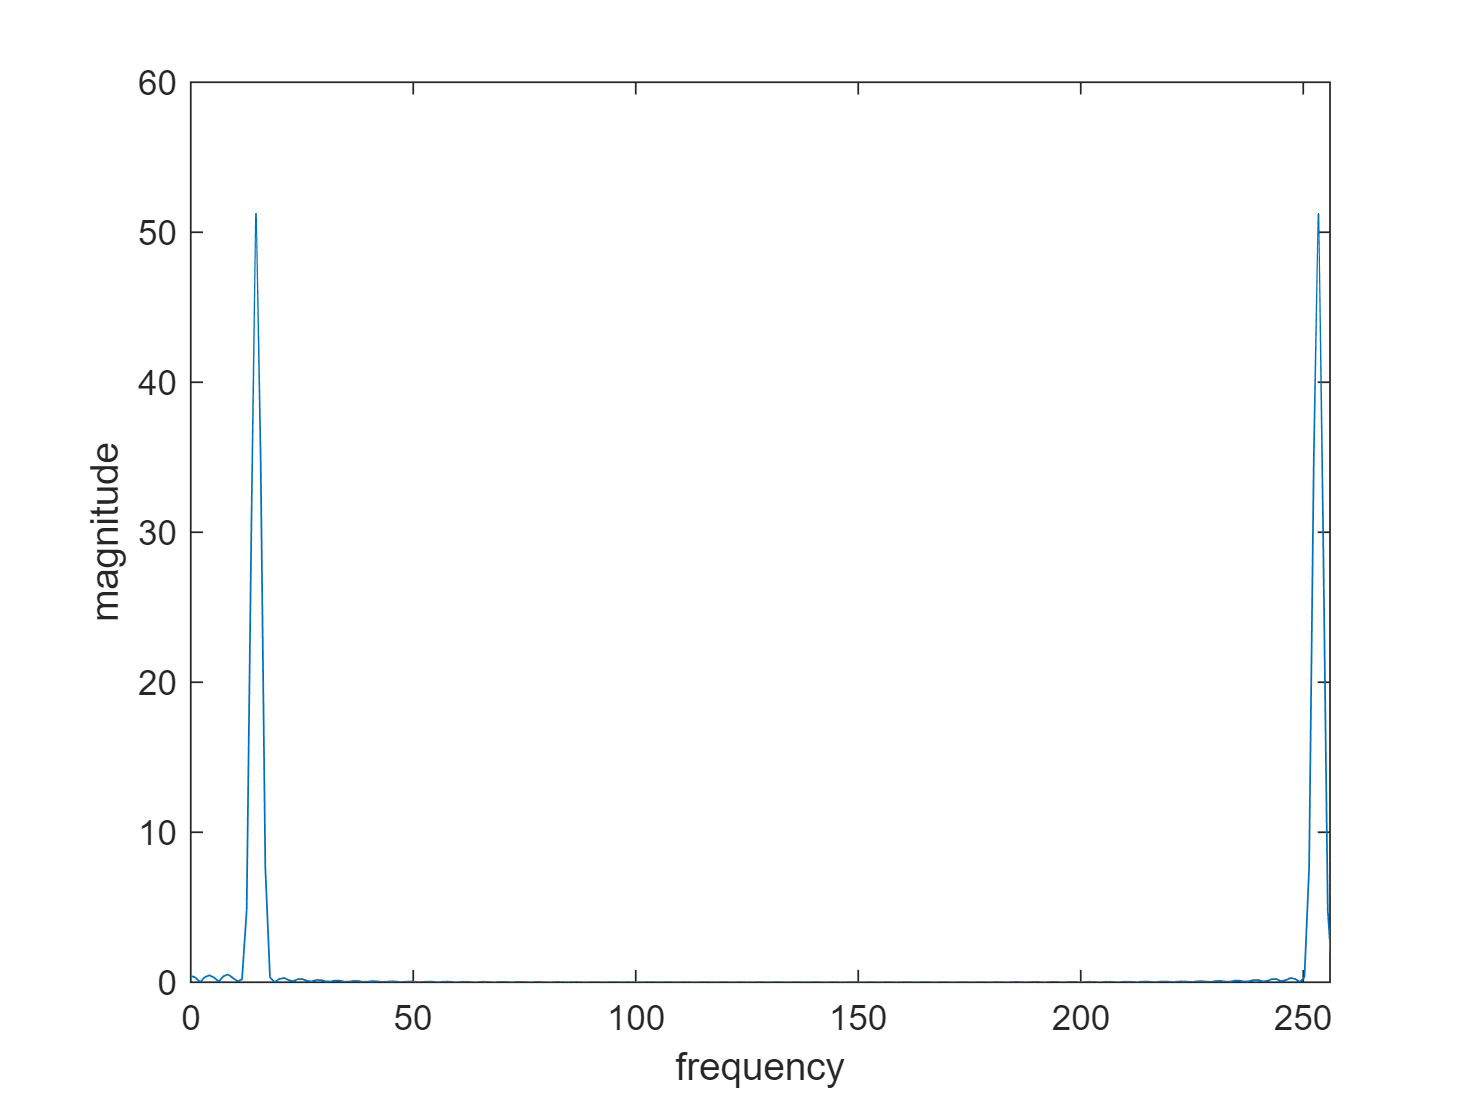

plot(f,abs(X2))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

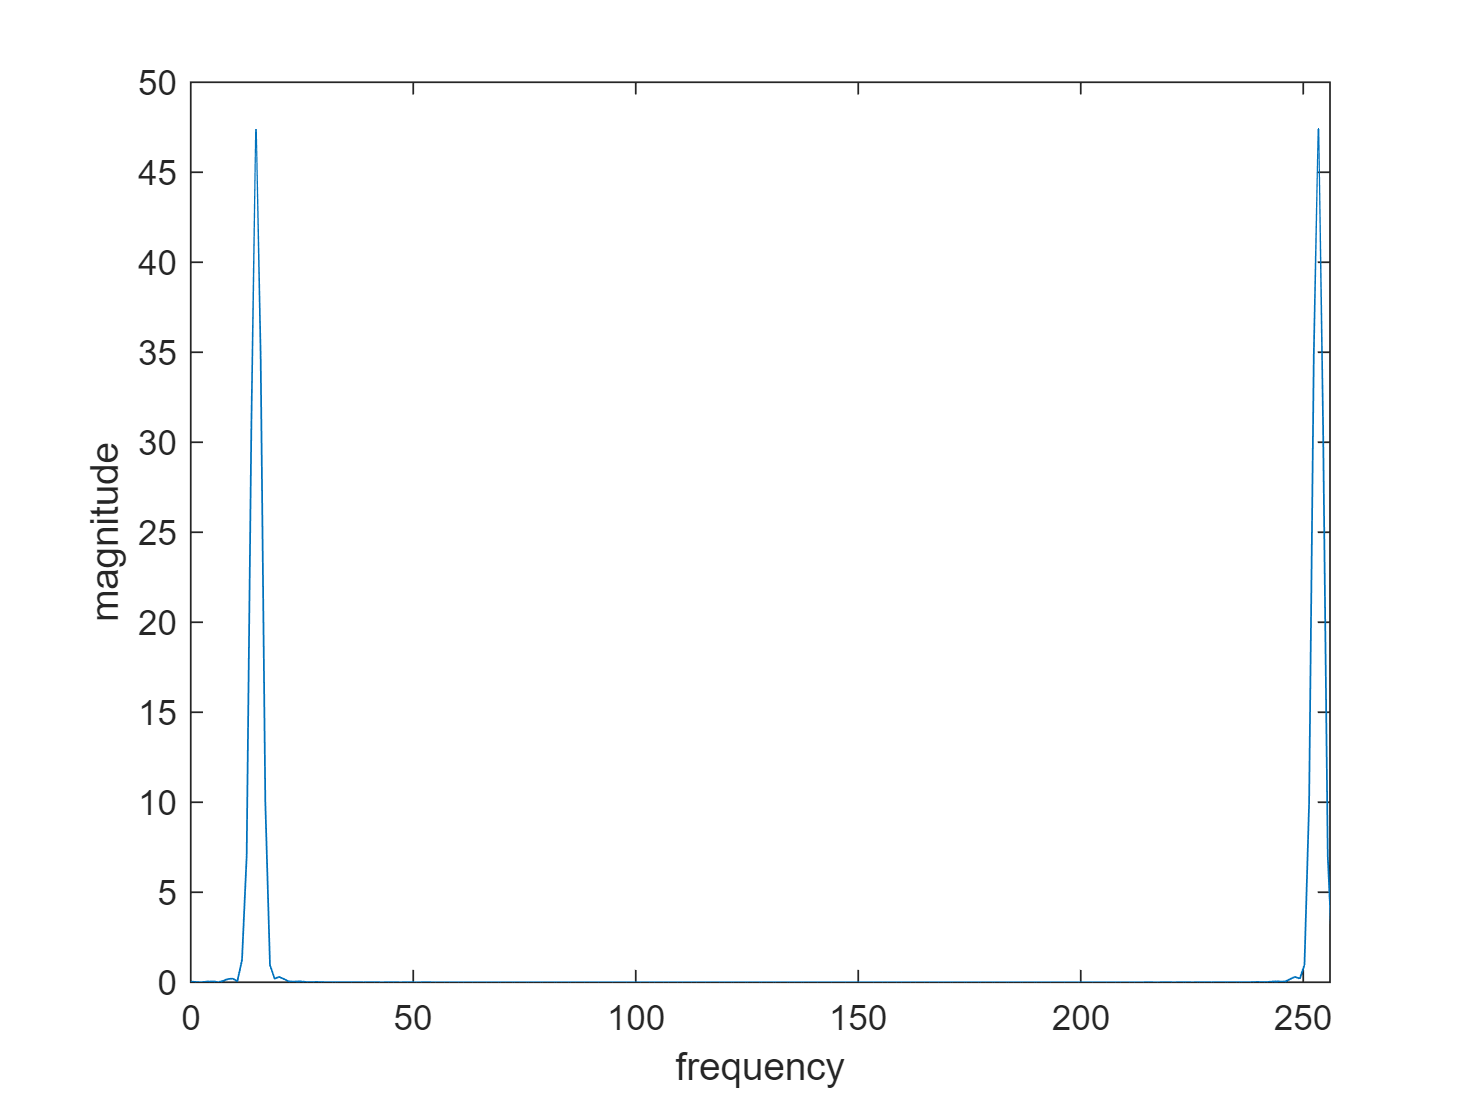

plot(f,abs(X3))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

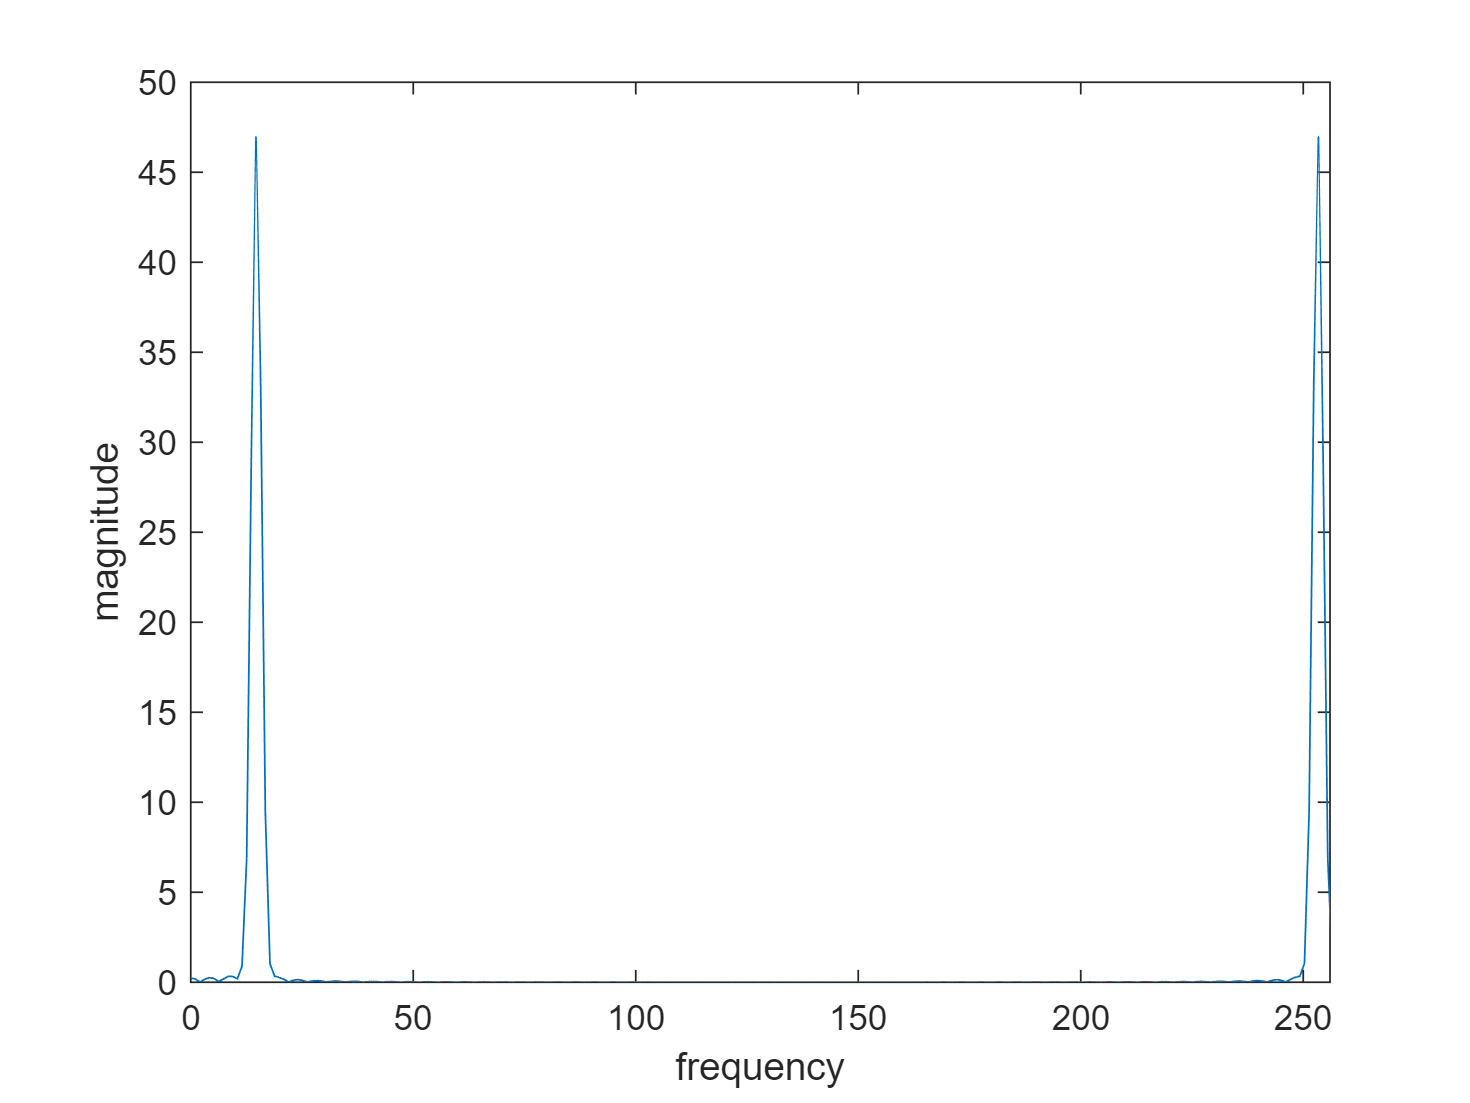

plot(f,abs(X4))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');